
clear all
close all
clc


## 1. Parametros fisicos e geometricos

k_gelo = 2.22;          % Condutividade termica [W/(m.K)]
qdot = 0;               % Fonte interna [W/m^3]
rho_gelo = 917;         % Densidade [kg/m^3]
cp_gelo = 2100;         % Calor especifico [J/(kg.K)]

T_meio = 20;    % Temperatura do meio exterior [°C]
h = 15;             % Coeficiente de convecção [W/(m^2*K)]

T_inicial = 0;      % Temperatura inicial do gelo [°C]
Lx = 0.5;
Ly = 0.5;
Lz = 0.5;

Nx = 10;    % Mallha simetrica, com o mesmo numero de nos
Ny = 10;
Nz = 10;

x = linspace(0,Lx,Nx+1);
y = linspace(0,Ly,Ny+1);
z = linspace(0,Lz,Nz+1);

[X,Y,Z] = meshgrid(x,y,z);

N_nos = numel(X);

coord = [X(:),Y(:),Z(:)];


## 2. Matriz de conectividade

elem = zeros(6*Nx*Ny*Nz,4);

e = 0;

for k = 1:Nz
    for j = 1:Ny
        for i = 1:Nx

            n1 = (k-1)*(Nx+1)*(Ny+1) ...
                +(j-1)*(Nx+1)+i;

            n2 = n1+1;
            n3 = n1+(Nx+1);
            n4 = n3+1;

            n5 = n1+(Nx+1)*(Ny+1);
            n6 = n5+1;
            n7 = n5+(Nx+1);
            n8 = n7+1;

            Tetra = [
                n1 n2 n4 n8;
                n1 n4 n3 n8;
                n1 n3 n7 n8;
                n1 n7 n5 n8;
                n1 n5 n6 n8;
                n1 n6 n2 n8
            ];

            elem(e+1:e+6,:) = Tetra;

            e = e+6;

        end
    end
end

Ne = size(elem,1);


## 3. Inicializacao das matrizes globais

K = zeros(N_nos,N_nos);
M = zeros(N_nos,N_nos);
F = zeros(N_nos,1);


## 4. Assemblagem FEM 3D

for e = 1:Ne

    nos = elem(e,:);

    xe = coord(nos,1);
    ye = coord(nos,2);
    ze = coord(nos,3);

    P = [ones(4,1), xe, ye, ze];

    Ve = abs(det(P))/6;

    % Coeficientes das funcoes de forma
    C = P\eye(4);

    % Matriz das derivadas
    B = C(2:4,:);

    % Matriz de conducao termica
    Ke = k_gelo*Ve*(B'*B);

    % Matriz de massa termica
    Me = (rho_gelo*cp_gelo*Ve/20)* ...
        [2 1 1 1;
         1 2 1 1;
         1 1 2 1;
         1 1 1 2];

    % Vetor de fontes termicas
    fe = (qdot*Ve/4)*ones(4,1);

    % Assemblagem global
    K(nos,nos) = K(nos,nos)+Ke;
    M(nos,nos) = M(nos,nos)+Me;
    F(nos) = F(nos)+fe;

end


## 5. Condições de fronteira - Convecção nas 6 faces

% Inicialização das matrizes de convecção
K_conv = zeros(N_nos,N_nos);
F_conv = zeros(N_nos,1);

% Construção de todas as faces triangulares dos tetraedros
faces = [
    elem(:,[1 2 3]);
    elem(:,[1 2 4]);
    elem(:,[1 3 4]);
    elem(:,[2 3 4])
];

% Ordenar os nós de cada face
faces = sort(faces,2);

% Identificar faces exteriores
[faces_unicas,~,ic] = unique(faces,'rows');

contagem = accumarray(ic,1);

% Faces que aparecem apenas uma vez são exteriores
faces_exteriores = faces_unicas(contagem == 1,:);

N_faces = size(faces_exteriores,1);

% Assemblagem das matrizes de convecção
for f = 1:N_faces

    nos = faces_exteriores(f,:);

    % Coordenadas dos três nós
    p1 = coord(nos(1),:);
    p2 = coord(nos(2),:);
    p3 = coord(nos(3),:);

    % Área do triângulo
    Af = 0.5*norm(cross(p2-p1,p3-p1));

    % Matriz local de convecção
    Kf = (h*Af/12)*[
        2 1 1;
        1 2 1;
        1 1 2
    ];

    % Vetor local associado à temperatura exterior
    Ff = (h*T_meio*Af/3)*ones(3,1);

    % Assemblagem global
    K_conv(nos,nos) = K_conv(nos,nos)+Kf;

    F_conv(nos) = F_conv(nos)+Ff;

end

fprintf('Number of external faces: %d\n',N_faces);

Number of external faces: 1200


## 6. Resolução temporal - Crank Nicolson

dt = 10;
t_final = 1200; %[s]

Nt = round(t_final/dt);

% Temperatura inicial uniforme
T0 = T_inicial*ones(N_nos,1);

T = T0;

% Matrizes globais com convecção
K_total = K + K_conv;

F_total = F + F_conv;

% Matrizes de Crank-Nicolson
A = M + (dt/2)*K_total;

D = M - (dt/2)*K_total;

% Fatorização LU
[L,U] = lu(A);

% Armazenamento dos resultados
T_hist = zeros(N_nos,Nt+1);

T_hist(:,1) = T;

for n = 1:Nt

    % Termo independente
    rhs = D*T + dt*F_total;

    % Resolução do sistema
    T = U\(L\rhs);

    % Armazenamento
    T_hist(:,n+1) = T;

end


## 7. Temperatura média de cada elemento

T_elem = zeros(Ne,1);

for e = 1:Ne

    nos = elem(e,:);

    T_elem(e) = mean(T(nos));

end


## 8. Visualizacao da temperatura

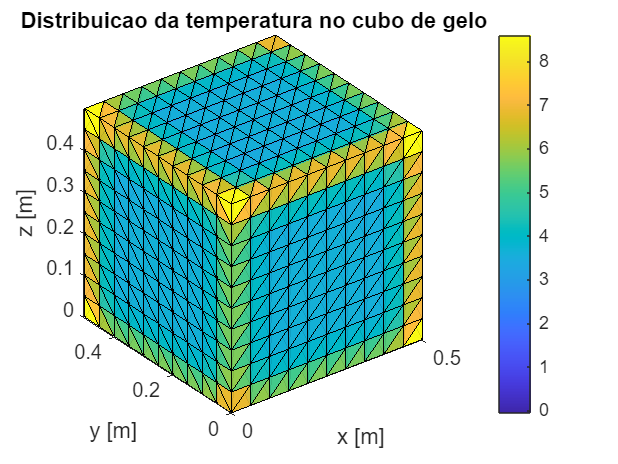

figure;

tetramesh(elem,coord,T_elem);

xlabel('x [m]');
ylabel('y [m]');
zlabel('z [m]');

title('Distribuicao da temperatura no cubo de gelo');

colorbar;
axis equal;
view(3);

## 9. Resultados

fprintf('Numero de nos: %d\n',N_nos);

Numero de nos: 1331


fprintf('Numero de elementos: %d\n',Ne);

Numero de elementos: 6000



fprintf('Temperatura minima: %.2f C\n',min(T));

Temperatura minima: -0.09 C


fprintf('Temperatura maxima: %.2f C\n',max(T));

Temperatura maxima: 11.24 C


fprintf('Tempo de exposição: %.2f segundos',t_final);

Tempo de exposição: 1200.00 segundos

fprintf('Numero de valores de temperatura: %d\n',length(T));

Numero de valores de temperatura: 1331
